# `iEITBacon Saline tank test`

#### **Details about experiment**

EIT experiments are conducted in a saline tank phantom to reconstruct images using the GN-Onestep solver. Several reconstruction priors are tested with various hyperparameters. The optimal hyperparamers are calculated by generalized cross-validantion(GCV)

**Priors used:**

- (NOS) - NOSER prior

- (LAP) - LAPLACE prior

- (TIK) - Tikhonov prior

- (GHPF) - Gaus HPF prior

**Test conducted where objects are placed at:**

- default: no object

- Center (CnC) Tests: Center nonCond

- Edge (EnC - E71) Tests: Target between E7 AND E1

- Edge (EnC - E53) Tests: Target between E5 AND E3 

- Center (CC) Tests: Center Cond

- Edge (EC - E71) Tests: Target between E7 AND E1

- Edge (EC - E53) Tests: Target between E5 AND E3 

- 2obj (EnC-E71 + EC-E31): conductive Target between E3 AND E1,nonConductive Target between E7 AND E1

- 4obj(EnC-E71,E53 + EC-E31,E57): conductive Target between E3&E1+E7&E1  ,nonConductive Target between E5&E3 + E5&E7 

#### **Details about experimental setup**

- Number electrodes = 8

- Stimulation pattern = adjacent 

- Measurement pattern => adjacent

- Stimmulation frequency = 25kHz

- tank diameter = 155mm

- Solution volume = 100ml or 250ml

- Saline solution = 36.7g/L

## `Start up`

`Refer to EIDORS website for initial setup and package installation`

[`https://eidors3d.sourceforge.net/`](https://eidors3d.sourceforge.net/)

%run startup.m %uncomment on first run

## setup

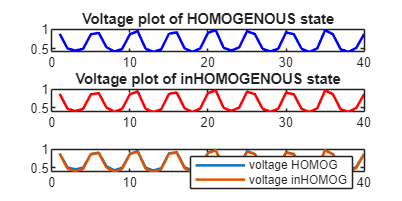

%% 1. Load Data & Setup Model
v_homg = load('iEITBacon_Too_tests\Saline_Tank_Test10_8E_250ml_2026-03-23\T10-chan8-Tank-DEFAULT-NoObj-F_25kHz-V_250-d_155mm-med_Saline_36.7gL.txt'); 
v_inhomg = load('iEITBacon_Too_tests\Saline_Tank_Test10_8E_250ml_2026-03-23\T10-chan8-Tank-CC-F_25kHz-V_250ml-d_155mm.txt');

figure('Name', 'Saline Tank Test7 500ml voltages', 'Position', [100 100 800 400]);

subplot(3,1, 1);
plot(v_homg,'b' , 'LineWidth', 1.5);
title('Voltage plot of HOMOGENOUS state')

subplot(3,1, 2);
plot(v_inhomg, 'r','LineWidth', 1.5);
title('Voltage plot of inHOMOGENOUS state')
subplot(3,1, 3);
plot([v_homg, v_inhomg], 'LineWidth', 1.5);
legend('voltage HOMOG','voltage inHOMOG');

## FEM model

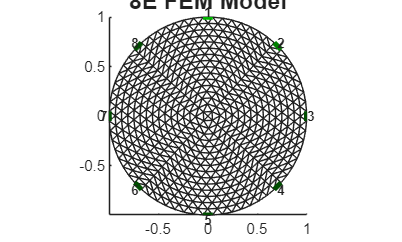


fmdl = mk_common_model('d2C2', 8); %distmesh = d2d4c %circ meash c2C2
[stim, msel] = mk_stim_patterns(8, 1, '{ad}', '{ad}', {'no_meas_current'}, 0.65); %stim pattern init, don't include stimmulation electrodes
fmdl.fwd_model.stimulation = stim;
fmdl.fwd_model.meas_select = msel;
figure('Name', 'Forward Model Mesh');
show_fem(fmdl.fwd_model,[0,1])
title('8E FEM Model', 'FontSize', 14, 'FontWeight', 'bold');

## Solve inverse problem

imdl = eidors_obj('inv_model', 'EIT_Inverse');
imdl.reconst_type = 'difference';
imdl.jacobian_bkgnd.value = 1;
imdl.fwd_model = fmdl.fwd_model;
imdl.solve = @inv_solve_diff_GN_one_step;

%Hyperparamer values
%
%Calculate optimal Hyperparameter for prior, and scale it using different
%weights to see impact
%
hp_multipliers = [0.001 ,0.01, 0.1, 1, 10, 100, 1000];
hp_labels = {'\lambda/1000' , '\lambda/100', '\lambda/10', 'Opt \lambda', '\lambda*10', '\lambda*100', '\lambda*1000'};

% Pre-allocate cell arrays to store the image structures
imgs_laplace  = cell(1, 7);
imgs_noser    = cell(1, 7);
imgs_tikhonov = cell(1, 7);
imgs_GHPF = cell(1, 7);


% Iterate through the three priors for each hyperparamete weight

priors = {@prior_laplace, @prior_noser, @prior_tikhonov, @prior_gaussian_HPF};
prior_names = {'Laplace', 'NOSER', 'Tikhonov','Gaus_HPF'};

for p = 1:4
    fprintf('Computing solutions for %s prior...\n', prior_names{p});
    imdl.RtR_prior = priors{p};

    % Calculate base lambda
    lambda_base = calc_lambda_regtools(imdl, v_homg, v_inhomg, 'GCV', false);
    close(gcf); 

    for i = 1:7
        imdl.hyperparameter.value = lambda_base * hp_multipliers(i);
        switch p
            case 1, imgs_laplace{i}  = inv_solve(imdl, v_homg, v_inhomg);
            case 2, imgs_noser{i}    = inv_solve(imdl, v_homg, v_inhomg);
            case 3, imgs_tikhonov{i} = inv_solve(imdl, v_homg, v_inhomg);
            case 4, imgs_GHPF{i} = inv_solve(imdl, v_homg, v_inhomg);
        end
    end
end

Computing solutions for Laplace prior...


  03-May-2026 12:46:59: Calculating lambda for each frame:  Calculating lambda for each frame: (0.139 s)


Computing solutions for NOSER prior...


  03-May-2026 12:47:00: Calculating lambda for each frame:  Calculating lambda for each frame: (0.112 s)


Computing solutions for Tikhonov prior...


  03-May-2026 12:47:01: Calculating lambda for each frame:  Calculating lambda for each frame: (0.240 s)


Computing solutions for Gaus_HPF prior...


  03-May-2026 12:47:03: Calculating lambda for each frame:  Calculating lambda for each frame: (0.095 s)


## Plot reconstructed images

figure('Name', 'Prior vs Hyperparameter Grid', 'Position', [50, 50, 1000, 550]);
t = tiledlayout(4, 7, 'TileSpacing', 'compact', 'Padding', 'compact');

%Laplace prior
for i = 1:7
    nexttile;
    show_fem(imgs_laplace{i}, [0,1]);
    
    title(sprintf('Laplace: %s', hp_labels{i}));

    
end


%NOSER  prior
for i = 1:7
    nexttile;
    show_fem(imgs_noser{i}, [0,1]);
    title(sprintf('NOSER: %s', hp_labels{i}));
end


%Tikhonov  prior
for i = 1:7
    nexttile;
    show_fem(imgs_tikhonov{i}, [0,1]);
    title(sprintf('Tikhonov: %s', hp_labels{i}));
end


%Gaus HPF prior
for i = 1:7
    nexttile;
    show_fem(imgs_GHPF{i}, [0,1]);
    title(sprintf('Gaus HPF: %s', hp_labels{i}));
end

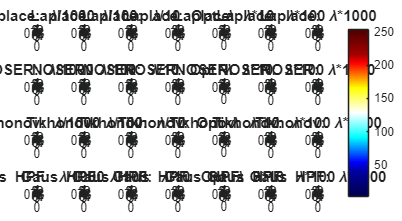

cb = colorbar;
cb.Layout.Tile = 'east';